# Assured Allies assignment Nofi

## control Analysis

control group rate of Long Term Care Utilization

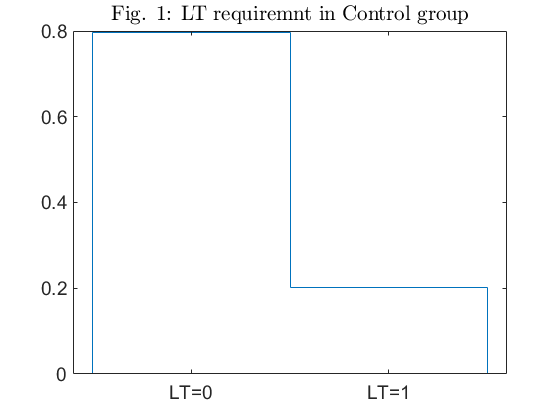

figure
Cntrl=tab.group=="control" ;
histogram(tab.ltcb(Cntrl),'DisplayStyle',"stairs",'DisplayName','Long Term Care 0',...
    'Normalization',"probability");
set(gca,'XTick',[0 1],'XTickLabel',{'LT=0','LT=1'},'fontsize',14)
titlemine('Fig. 1: LT requiremnt in Control group');

parsing men and women

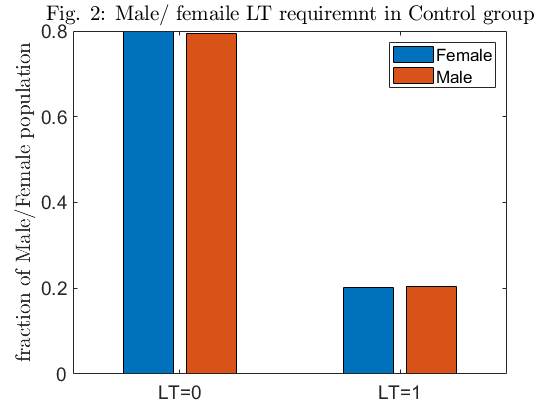

figure
CntrlW=tab.group=="control" & tab.gender==1;
CntrlM=tab.group=="control" & tab.gender==0;

WMlt1=sum(tab.ltcb(CntrlW)==1);
WMlt0=sum(tab.ltcb(CntrlW)==0);

MNlt1=sum(tab.ltcb(CntrlM)==1);
MNlt0=sum(tab.ltcb(CntrlM)==0);



figure
bar([0  1],[[WMlt0 WMlt1]./sum(CntrlW); [MNlt0 MNlt1]./sum(CntrlM)]')
ylabelmine('fraction of Male/Female population');
set(gca,'XTickLabel',{'LT=0','LT=1'},'fontsize',14)
legend({'Female','Male'})

titlemine('Fig. 2: Male/ femaile LT requiremnt in Control group');

parsing by age groups fo 'LT needed' populaion  

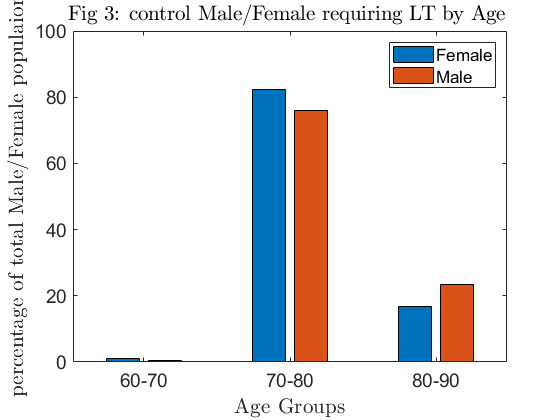

% bin by ages
ageBins=60:10:90;
binInd=discretize(tab.age,ageBins);


baseMask=tab.group=='control' & tab.ltcb==1;

femMask=baseMask & tab.gender==1;
malMask=baseMask & tab.gender==0;


femCount=[ sum(binInd(femMask)==1) sum(binInd(femMask)==2) sum(binInd(femMask)==3)  ]./sum(femMask).*100;
malCount=[ sum(binInd(malMask)==1) sum(binInd(malMask)==2) sum(binInd(malMask)==3)  ]./sum(malMask).*100;


figure
bar(1:3,[femCount ; malCount]')

set(gca,'XTickLabel',{'60-70','70-80','80-90'},'fontsize',14)
legend({'Female','Male'})

xlabelmine('Age Groups');
ylabelmine('percentage  of total Male/Female populaion');
titlemine('Fig 3: control  Male/Female requiring LT by Age ');

## exploring isolatio status

in the intervention gorup, among those that answered the questionnaire ,and are socially isolated 

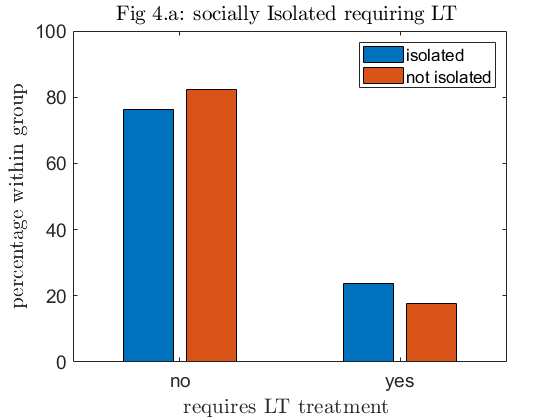

baseMask=tab.group=='intervention' & tab.questionnairecomplete=='1' ;% & tab.ltcb==1;

isoMask=baseMask & tab.socialisolationb=="1";
noIsoMask=baseMask & tab.socialisolationb=="0";

isoData=[sum(tab.ltcb(isoMask)==0), sum(tab.ltcb(isoMask)==1)]./sum(isoMask).*100;
noIsoData=[sum(tab.ltcb(noIsoMask)==0) , sum(tab.ltcb(noIsoMask)==1)]./sum(noIsoMask).*100;

figure
bar([0 1],[ isoData;noIsoData ]')      

set(gca,'XTickLabel',{'no' ,'yes'},'fontsize',14)
legend({'isolated','not isolated'})

xlabelmine('requires LT treatment ');
ylabelmine('percentage within group'); 
titlemine('Fig 4.a: socially Isolated requiring LT ');

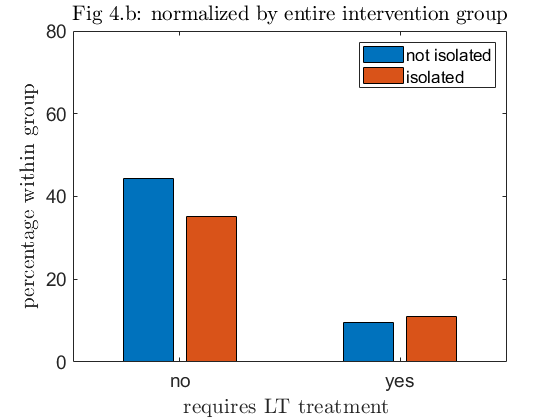




noLTData =[sum(tab.ltcb(noIsoMask)==0) sum(tab.ltcb(isoMask)==0)];
yesLTData=[sum(tab.ltcb(noIsoMask)==1) sum(tab.ltcb(isoMask)==1)];
figure
bar([0 1],[ noLTData./sum(baseMask) ; yesLTData./sum(baseMask)].*100    )      

set(gca,'XTickLabel',{'no' ,'yes'},'fontsize',14)
legend({'not isolated','isolated'})
ylim([0 80])
xlabelmine('requires LT treatment ');
ylabelmine('percentage within group'); %  of total Male/Female populaion');
titlemine('Fig 4.b: normalized by entire intervention group');

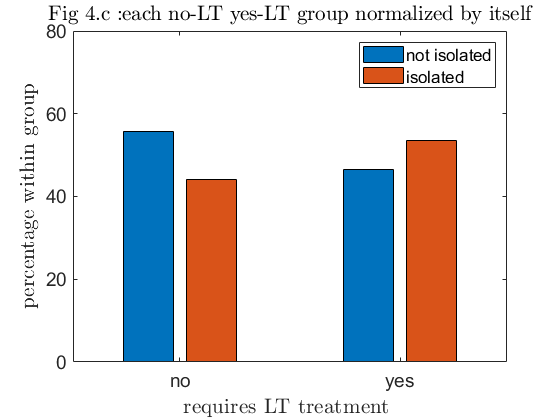



figure
bar([0 1],[ noLTData./sum(noLTData) ; yesLTData./sum(yesLTData)].*100    )      

set(gca,'XTickLabel',{'no' ,'yes'},'fontsize',14)
legend({'not isolated','isolated'})
ylim([0 80])
xlabelmine('requires LT treatment ');
ylabelmine('percentage within group'); %  of total Male/Female populaion');
titlemine('Fig 4.c :each no-LT yes-LT group normalized by itself');

To tet the siginificance of the result we perform a t-test  comparing the control group and isolated group, with respect to those who require long-term treatment. : 

[h,p]=ttest2(tab.ltcb(Cntrl),tab.ltcb(isoMask));

fprintf('Result of the t-test: There is a significant difference between control and Isolated groups, with significance of p=%f',p)

Result of the t-test: There is a significant difference between control and Isolated groups, with significance of p=0.002567


%risk_factor=

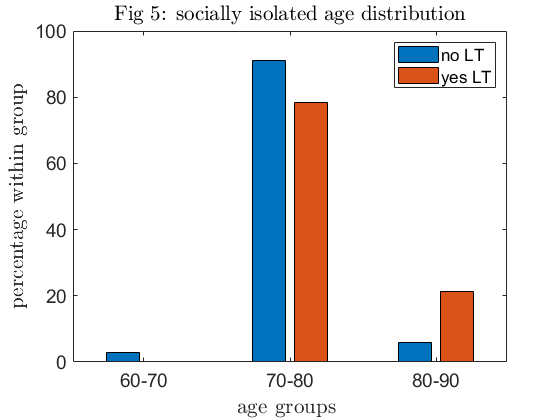

% parse by age 

baseMask=tab.group=='intervention' & tab.questionnairecomplete=='1' ; % & tab.ltcb==1;

isoMask=baseMask & tab.socialisolationb=="1";
noIsoMask=baseMask & tab.socialisolationb=="0";

fac0=sum(tab.ltcb(isoMask)==0)./100;
fac1=sum(tab.ltcb(isoMask)==1)./100;

age1=[ sum(tab.ltcb(isoMask & binInd==1)==0)./fac0   sum(tab.ltcb(isoMask & binInd==1)==1)./fac1];
age2=[ sum(tab.ltcb(isoMask & binInd==2)==0)./fac0   sum(tab.ltcb(isoMask & binInd==2)==1)./fac1];
age3=[ sum(tab.ltcb(isoMask & binInd==3)==0)./fac0   sum(tab.ltcb(isoMask & binInd==3)==1)./fac1];

figure
bar([0 1 2],[ age1 ; age2 ; age3])      

set(gca,'XTickLabel',{'60-70' ,'70-80','80-90'},'fontsize',14)
legend({'no LT','yes LT'})

xlabelmine('age groups ');
ylabelmine('percentage within group'); %  of total Male/Female populaion');
titlemine('Fig 5: socially isolated age distribution');

of the socially isolated group, see LT requirement with volunteer status 

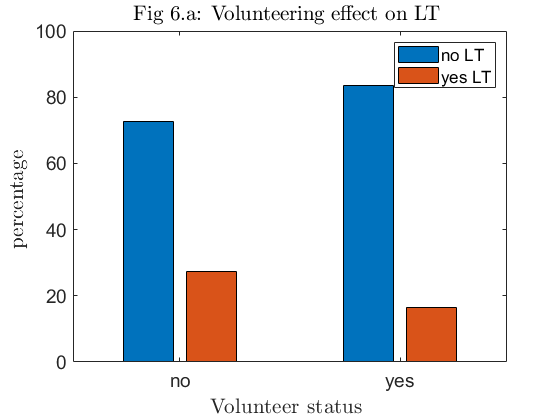

baseMask=tab.group=='intervention' & tab.questionnairecomplete=='1' & tab.socialisolationb=="1";% & tab.ltcb==1;

volMask=baseMask & tab.volunteerb=="1";
noVolMask=baseMask & tab.volunteerb=="0";

% fac0=sum(tab.ltcb(baseMask)==0)./100;
% fac1=sum(tab.ltcb(baseMask)==1)./100;

noVData=[ sum(tab.ltcb(noVolMask)==0) sum(tab.ltcb(noVolMask)==1) ]./sum(noVolMask).*100 ;
yesVData=[ sum(tab.ltcb(volMask)==0), sum(tab.ltcb(volMask)==1) ]./sum(volMask).*100 ;

  

figure
bar([0 1],[ noVData ; yesVData])      

set(gca,'XTickLabel',{'no' ,'yes'},'fontsize',14)
legend({'no LT','yes LT'})
ylim([0 100])
xlabelmine('Volunteer status ');
ylabelmine('percentage '); %  of total Male/Female populaion');
titlemine('Fig 6.a: Volunteering effect on LT  ');

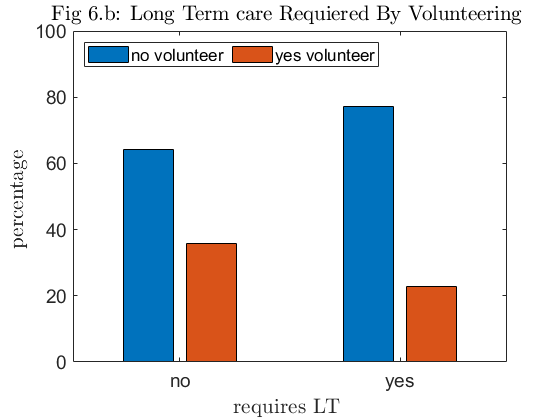


noLTData=[ sum(tab.ltcb(noVolMask)==0) sum(tab.ltcb(volMask)==0) ]./fac0;%./sum(noVolMask).*100 ;
yesLTData=[ sum(tab.ltcb(noVolMask)==1), sum(tab.ltcb(volMask)==1)]./fac1;% ]./sum(volMask).*100 ;

  

figure
bar([0 1],[ noLTData ; yesLTData])      

set(gca,'XTickLabel',{'no' ,'yes'},'fontsize',14)
legend({'no volunteer','yes volunteer'},'location','northwest','NumColumns',2)
ylim([0 100])
xlabelmine('requires LT ');
ylabelmine('percentage '); %  of total Male/Female populaion');
titlemine('Fig 6.b: Long Term care Requiered By Volunteering ');

We perform a t-test to find whether the difference between the volunteering and non-volunteering group is significant: 

[h2,p2]=ttest2(tab.ltcb(noVolMask),tab.ltcb(volMask));
fprintf('Result of the t-test: There is a significant difference between the gorups, with significance of p=%f',p2)

Result of the t-test: There is a significant difference between the gorups, with significance of p=0.000002